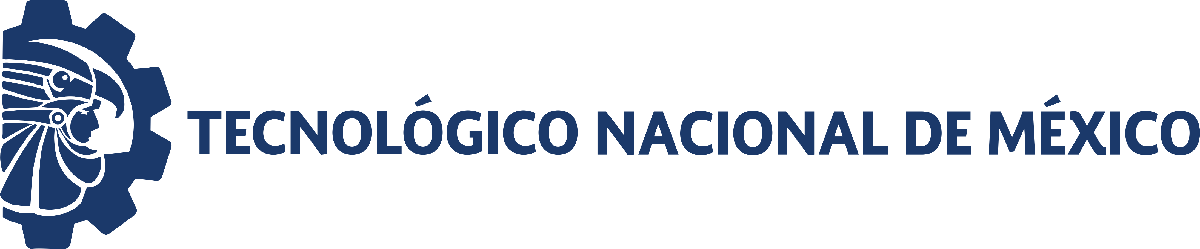                                 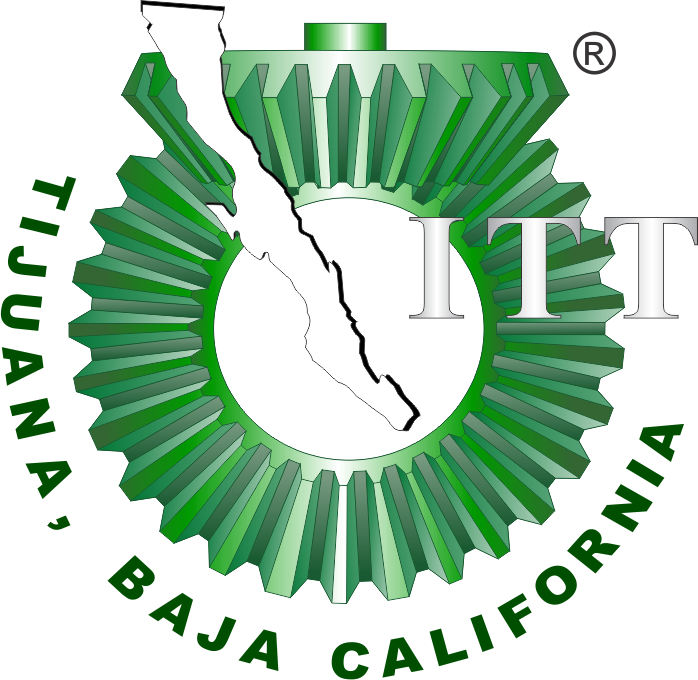

# Práctica uno: Diseño de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general           

##           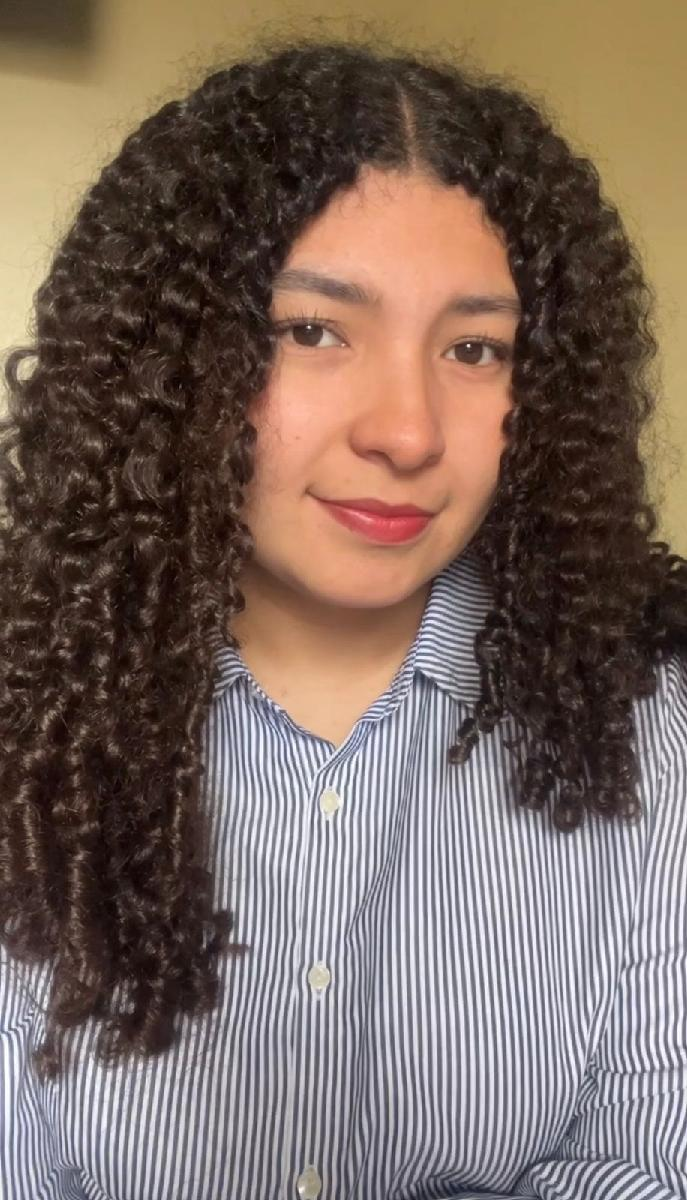

Nombre del alumno: Johana Jazmin De La Torre Gomez

Número de control: 22211751

Correo institucional: l22211751**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('Practica1/VS1(t)','VectorFormat','1-D array');

## Respuesta al escalón

Signal = 'Step';
set_param('Practica1/S1', 'sw', '1');
set_param('Practica1/Ve(t)', 'sw', '1');
x1 = sim(file,parameters);

Found algebraic loop containing: 
Practica1/VS3(t)/1//3R
Practica1/VS3(t)/R
Practica1/VS3(t)/L
Practica1/VS3(t)/Derivative2
Practica1/VS3(t)/Add
Practica1/VS3(t)/1//2R
Practica1/VS3(t)/R2
Practica1/VS3(t)/Add2 (algebraic variable)
Practica1/VS3(t)/Add1 (algebraic variabl

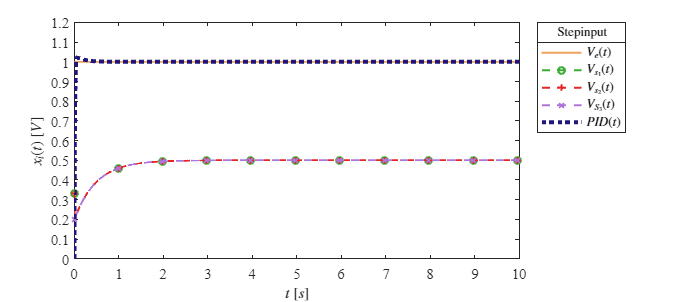

plotsignals(x1.t,x1.Ve,x1.VS1,x1.VS2,x1.VS3,x1.PID,Signal)

## Respuesta al impulso

Signal = 'Impulse';
set_param('Practica1/S1', 'sw', '0');
set_param('Practica1/Ve(t)', 'sw', '1');
x2 = sim(file,parameters);

Found algebraic loop containing: 
Practica1/VS3(t)/1//3R
Practica1/VS3(t)/R
Practica1/VS3(t)/L
Practica1/VS3(t)/Derivative2
Practica1/VS3(t)/Add
Practica1/VS3(t)/1//2R
Practica1/VS3(t)/R2
Practica1/VS3(t)/Add2 (algebraic variable)
Practica1/VS3(t)/Add1 (algebraic variabl

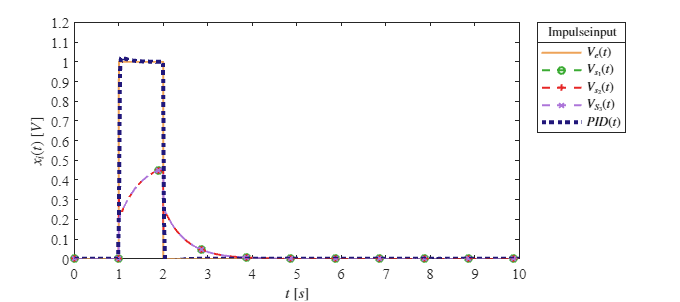

plotsignals(x2.t,x2.Ve,x2.VS1,x2.VS2,x2.VS3,x2.PID,Signal)

## Respuesta a la rampa

Signal = 'Ramp';
set_param('Practica1/S2', 'sw', '1');
set_param('Practica1/Ve(t)', 'sw', '0');
x3 = sim(file,parameters);

Found algebraic loop containing: 
Practica1/VS3(t)/1//3R
Practica1/VS3(t)/R
Practica1/VS3(t)/L
Practica1/VS3(t)/Derivative2
Practica1/VS3(t)/Add
Practica1/VS3(t)/1//2R
Practica1/VS3(t)/R2
Practica1/VS3(t)/Add2 (algebraic variable)
Practica1/VS3(t)/Add1 (algebraic variabl

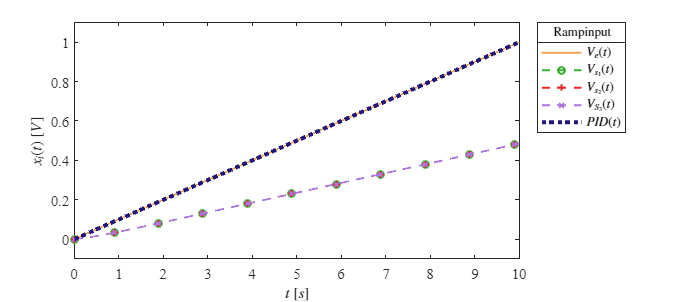

plotsignals(x3.t,x3.Ve,x3.VS1,x3.VS2,x3.VS3,x3.PID,Signal)

## Respuesta a la función sinusoidal

Signal = 'Sin';
set_param('Practica1/S2', 'sw', '0');
set_param('Practica1/Ve(t)', 'sw', '0');
x4 = sim(file,parameters);

Found algebraic loop containing: 
Practica1/VS3(t)/1//3R
Practica1/VS3(t)/R
Practica1/VS3(t)/L
Practica1/VS3(t)/Derivative2
Practica1/VS3(t)/Add
Practica1/VS3(t)/1//2R
Practica1/VS3(t)/R2
Practica1/VS3(t)/Add2 (algebraic variable)
Practica1/VS3(t)/Add1 (algebraic variabl

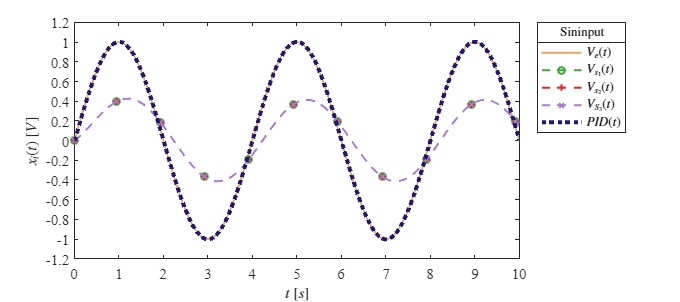

plotsignals(x4.t,x4.Ve,x4.VS1,x4.VS2,x4.VS3,x4.PID,Signal)

## Funcion: Respuesta a las señales

function plotsignals (t,Ve,VS1,VS2,VS3,PID,Signal)
    set(figure(),'Color',"W")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;   
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

p = plot(t,Ve,'-',t,VS1,'--o',t,VS2,'--+',t,VS3,'--x',t,PID,':',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(5),'LineWidth',3)
L = legend('$V_e(t)$','$V_{s_1}(t)$','$V_{s_2}(t)$','$V_{S_3}(t)$', '$PID(t)$');
set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
title(L,[Signal,'input'],'FontSize',10)

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    if Signal == "Step" || Signal == "Impulse"
        ylim([0,1.2]); yticks(0:0.1:1.2);
    elseif Signal == "Ramp"
        ylim([-0.1 1.1]); yticks (-0.2:0.2:1.2);
    elseif Signal == "Sin"
        ylim([-1.2 1.2]); yticks (-1.2:0.2:2);
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end
